### **Aplicação do Algoritmo Genético**

INPUT.world.gravity = 9.81;  %(m/s²)
INPUT.world.density = 1.108; %(kg/m³)
INPUT.world.friction = 0.04;
INPUT.decisions.TO_dist = 55; %(m)
INPUT.decisions.obstacle = 0.8; %(m)
INPUT.decisions.friction_drag = 0.016;
INPUT.decisions.wing_density = 1.5;

GENETIC_PARAMETERS.cons = [0.200 0.500    % Corda na Raíz (m)
                           0.200 1.000    % Razão de Afilamento (%)
                           2.000 3.600    % Envergadura (m)
                           0.200 1.000    % Posição de Afilamento (%)
                           0.000 0.080    % Offset na Ponta
                           0.000 1.000    % Torção Intermediária (cat)
                           0.000 1.000    % Torção na Ponta (cat)
                           0.000 1.000    % Aerofólio (cat)                           
                           0.000 1.000];  % Grupo Motopropulsor (cat)

GENETIC_PARAMETERS.max_generations = 100;
GENETIC_PARAMETERS.pop_size = 30;
GENETIC_PARAMETERS.prob_crossover = 0.8;
GENETIC_PARAMETERS.prob_mutation = 0.25;
GENETIC_PARAMETERS.elitism_preservation = 2;

[GENETIC_OUTPUTS] = GA_ELITISM(INPUT, GENETIC_PARAMETERS);

### Plot do Gráfico de Gerações

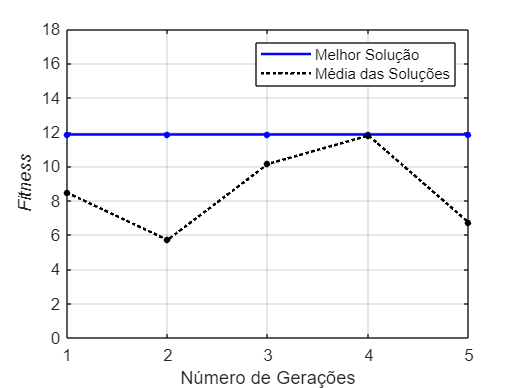

figure;
plot(1:GENETIC_PARAMETERS.max_generations, GENETIC_OUTPUTS.best_fitnesses, 'LineWidth',1.5, 'Color', 'blue');
hold on
plot(1:GENETIC_PARAMETERS.max_generations, GENETIC_OUTPUTS.mean_fitnesses, 'LineWidth',1.5, 'Color', 'black','LineStyle',':');
hold on
scatter(1:GENETIC_PARAMETERS.max_generations, GENETIC_OUTPUTS.best_fitnesses, 15, 'blue', 'filled');
hold on
scatter(1:GENETIC_PARAMETERS.max_generations, GENETIC_OUTPUTS.mean_fitnesses, 15, 'black', 'filled');

xlabel('Número de Gerações');
ylabel('\itFitness\rm');
legend('Melhor Solução','Média das Soluções', 'Location', 'northeast')
axis([1 GENETIC_PARAMETERS.max_generations 0 18]);
grid on;
set(gcf,'PaperPositionMode','auto')
print('Evolution','-dpng','-r450')

figure;
set(figure, 'Units', 'centimeters', 'Position', [5, 5, 20, 10]); % 20 cm de largura e 10 cm de altura
plot(1:GENETIC_PARAMETERS.max_generations, GENETIC_OUTPUTS.best_fitnesses, 'LineWidth',1.5, 'Color', 'blue');
hold on
scatter(1:GENETIC_PARAMETERS.max_generations, GENETIC_OUTPUTS.best_fitnesses, 15, 'blue', 'filled');

xlabel('Número de Gerações');
ylabel('\itFitness\rm');
legend('Melhor Solução', 'Location', 'northeast')
axis([1 GENETIC_PARAMETERS.max_generations 0 15]);
grid on;
set(gcf, 'PaperOrientation', 'landscape'); % Define a orientação como paisagem
set(gcf, 'PaperPositionMode', 'auto'); % Ajusta o gráfico na folha
print('Grande','-dpng','-r450')

### Plot do Gráfico de Todos on Indivíduos

filtered_solution = unique(GENETIC_OUTPUTS.all_solutions(:,1:10), 'rows');

rank = filtered_solution(:,10);

[rank, sort_order] = sort(rank, 'descend');
ordened_solutions = filtered_solution(sort_order, :);

area = [];
peso_vazio = [];
AR = [];

for i = 1 : 12
    c1 = ordened_solutions(i,1);
    c2 = ordened_solutions(i,1) * ordened_solutions(i,2);
    b = ordened_solutions(i,3)/2;
    b1 = b * ordened_solutions(i,4);
    S = 2*((c1 * b1) + (((c1 + c2)*(b - b1))/2));
    area(i,:) = S;
    peso_vazio(i,:) = S * 1.5;
    AR(i,:) = (ordened_solutions(i,3)*ordened_solutions(i,3))/S;
end

for i = 1 : 2795
    INPUT.world.gravity = 9.81;  %(m/s²)
    INPUT.world.density = 1.108; %(kg/m³)
    INPUT.world.friction = 0.04;
    INPUT.decisions.TO_dist = 55; %(m)
    INPUT.decisions.obstacle = 0.8; %(m)
    INPUT.decisions.friction_drag = 0.016;
    INPUT.decisions.wing_density = 1.5;
    INPUT.design.chord_r = ordened_solutions(i,1);
    INPUT.design.taper = ordened_solutions(i,2);
    INPUT.design.span = ordened_solutions(i,3);
    INPUT.design.y_taper = ordened_solutions(i,4);
    INPUT.design.offset_tip = ordened_solutions(i,5);
    twist_mid = [0.0 -1.0 -2.0 -3.0];
    n = find(ordened_solutions(i,6) <= [0.25 0.50 0.75 1.00], 1, 'first');
    INPUT.design.twist_mid = twist_mid(n);
    twist_tip = [twist_mid(n) twist_mid(n)-1 twist_mid(n)-2 twist_mid(n)-3];
    n = find(ordened_solutions(i,7) <= [0.25 0.50 0.75 1.00], 1, 'first');
    INPUT.design.twist_tip = twist_tip(n);
    airfoil = ["E423.dat" "UruA84212.dat" "UruA94113.dat" "UruA104612.dat"];
    n = find(ordened_solutions(i,8) <= [0.25 0.50 0.75 1.0], 1, 'first');
    INPUT.design.airfoil = airfoil(n);

    GMP = [[-0.0249 -1.2568 102.3320]
              [-0.0273 -0.07934 115.8218]
              [-0.0282 -0.2911 122.6452]
              [-0.0332 -2.3898 116.6083]
              [-0.0284 -1.5923 125.6174]
              [-0.0311 -1.0840 143.4866]
              [-0.0330 -0.4877 154.1342]];
    n = find(ordened_solutions(i,9) <= [0.143 0.286 0.429 0.572 0.715 0.858 1.000], 1, 'first');
    INPUT.design.power_plant = GMP(n,:);

    max  = PERFORMANCE_ANALYSIS (INPUT);
    MTOW = max.performance.MTOW;
    fit = 1/MTOW;

    MTOW_list(i,:) = fit;
end

 
  Athena Vortex Lattice  Program      Version  3.37 
  Copyright (C) 2002   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
   Quit    Exit program 
 
  .OPER    Compute operating-point run cases 
  .MODE    Eigenvalue analysis of run cases 
  .TIME    Time-domain calculations 
 
   LOAD f  Read configuration input file 
   MASS f  Read mass distribution file 
   CASE f  Read run case file 
 
   CINI    Clear and initialize run cases 
   MSET i  Apply mass file data to stored run case(s) 
 
  .PLOP    Plotting options 
   NAME s  Specify new configuration name 
 
 AVL   c>   
 Reading file: Astra.avl  ... 
 
 Configuration: Astra                                                        
 
   Building surface: Main W

Index in position 1 exceeds array bounds. Index must not exceed 12.


area
peso_vazio
AR
MTOW_list

MTOW_f = [];

for i = 1 : 2795
    MTOW_f(i,:) = 1/MTOW_list(i,:);
end

MTOW_f

final_solution = [ordened_solutions area peso_vazio AR MTOW_list]

### Gráfico de Evolução dos Indivíduos

top10 = final_solution(2:10, :);
top1 = final_solution(1, :);

x1 = final_solution(:,12)';
y1 = final_solution(:,14)';

x2 = top10(:,12)';
y2 = top10(:,14)';

x3 = top1(:,12)';
y3 = top1(:,14)';

figure;
scatter(x1, y1, 5, 'black', 'o');
hold on
scatter(x2, y2, 15, 'blue', 'filled');
hold on
scatter(x3, y3, 60, 'red', 'pentagram', 'filled');
xlabel('EW (kg)')
ylabel('MTOW^{-1} (kg^{-1})')
axis([0.5 2.5 0.03 0.09])
grid on;
set(gcf,'PaperPositionMode','auto')
print('Pareto','-dpng','-r450')

### Gráfico Fitness x Alongamento

x1 = final_solution(:,13)';
y1 = final_solution(:,10)';

x2 = top10(:,13)';
y2 = top10(:,10)';

x3 = top1(:,13)';
y3 = top1(:,10)';

figure;
scatter(x1, y1, 5, 'black', 'o');
hold on
scatter(x2, y2, 15, 'blue', 'filled');
hold on
scatter(x3, y3, 60, 'red', 'pentagram', 'filled');
xlabel('\itAR\rm')
ylabel('\itFitness\rm')
axis([3 18 0 15])
grid on;
set(gcf,'PaperPositionMode','auto')
print('1-AR','-dpng','-r450')

### Gráfico Fitness x Afilamento

x1 = final_solution(:,2)';
y1 = final_solution(:,10)';

x2 = top10(:,2)';
y2 = top10(:,10)';

x3 = top1(:,2)';
y3 = top1(:,10)';

figure;
scatter(x1, y1, 5, 'black', 'o');
hold on
scatter(x2, y2, 15, 'blue', 'filled');
hold on
scatter(x3, y3, 60, 'red', 'pentagram', 'filled');
xlabel('\lambda')
ylabel('\itFitness\rm')
axis([0 1 0 15])
grid on;
set(gcf,'PaperPositionMode','auto')
print('1-TAPER','-dpng','-r450')

### Gráfico Fitness x Alongamento x Afilamento

x1 = final_solution(:,13)';
y1 = final_solution(:,2)';
z1 = final_solution(:,10)';

x2 = top10(:,13)';
y2 = top10(:,2)';
z2 = top10(:,10)';

x3 = top1(:,13)';
y3 = top1(:,2)';
z3 = top1(:,10)';

figure;
scatter3(x1, y1, z1, 5, 'black', 'o');
hold on
scatter3(x2, y2, z2, 15, 'blue', 'filled');
hold on
scatter3(x3, y3, z3, 60, 'red', 'pentagram', 'filled');

xlabel('\itAR\rm')
ylabel('\lambda')
zlabel('\itFitness\rm')
set(gca,'XLim',[3 18],'YLim',[0.2 1],'ZLim',[0 15]);
grid on;
%set(gcf,'PaperPositionMode','auto')
%print('3D','-dpng','-r300')

### Gráfico Fitness x Aerofólio

x1 = final_solution(:,8)';
y1 = final_solution(:,10)';

x2 = top10(:,8)';
y2 = top10(:,10)';

x3 = top1(:,8)';
y3 = top1(:,10)';

figure;
scatter(x1, y1, 5, 'black', 'o');
hold on
scatter(x2, y2, 15, 'blue', 'filled');
hold on
scatter(x3, y3, 60, 'red', 'pentagram', 'filled');

text(0.1, 14, 'E423', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.25);
text(0.3, 14, 'UruA84212', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.50);
text(0.55, 14, 'UruA94113', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.75);
text(0.8, 14, 'UruA104612', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')

xlabel('Aerofólio')
ylabel('\itFitness\rm')
axis([0 1 0 15])
grid on;
%set(gcf,'PaperPositionMode','auto')
print('1-aerofolio','-dpng','-r450')

### Gráfico Fitness x Grupo Motopropulsor

x1 = final_solution(:,9)';
y1 = final_solution(:,10)';

x2 = top10(:,9)';
y2 = top10(:,10)';

x3 = top1(:,9)';
y3 = top1(:,10)';

figure;
scatter(x1, y1, 5, 'black', 'o');
hold on
scatter(x2, y2, 15, 'blue', 'filled');
hold on
scatter(x3, y3, 60, 'red', 'pentagram', 'filled');

text(0.03, 14, '17x8E', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.143);
text(0.165, 14, '17x10E', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.286);
text(0.308, 14, '17x12E', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.429);
text(0.432, 14, '18x5.5MR', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.572);
text(0.602, 14, '18x8E', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.715);
text(0.737, 14, '18x10E', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')
xline(0.858);
text(0.88, 14, '18x12E', 'FontSize', 9, 'Color', '#000000', 'FontWeight','bold')

xlabel('Sistema Propulsivo')
ylabel('\itFitness\rm')
axis([0 1 0 15])
grid off;
%set(gcf,'PaperPositionMode','auto')
print('1-SISTEMA PROPULSIVO','-dpng','-r450')